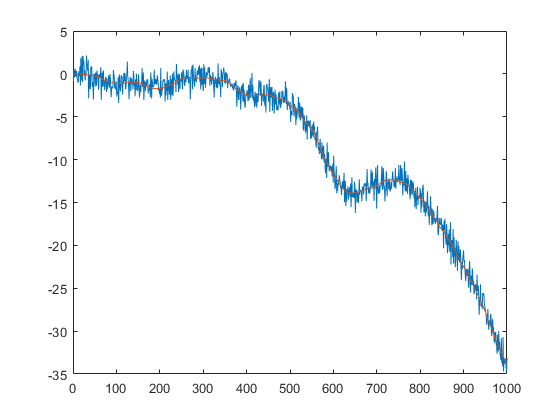

delta_t=0.1;

F = [1 delta_t; 0 1];
G = [delta_t^2/2; delta_t];
H = [1 0];

sigma_a = 0.5;
Q = 0.1;
R = 0.9;

N = 1000;
x0 = [0;0];

samples = linspace(0,1000, 1000);
a = randn(1,N)*sigma_a;

x_truth(:,1) = x0;

P_k_k = [0 0; 0 0];
x_k_k = x0;
for t=1:N
    x_truth(:,t+1) = F*x_truth(:,t) + G*a(t);
    y(t) = H*x_truth(:,t) + randn(1,1)*sqrt(R);
    
    % Prediction
    x_k1_k = F*x_k_k; % State estimate prediction
    P_k1_k = F*P_k_k*F.' + Q; % State estimate covariance
    
    % Measurement
    y_k = y(t);
    
    % Update
    m_k = y_k - H*x_k1_k; % Innovation
    S_k = H*P_k1_k*H.' + R; % Innovation covariance
    K_k = P_k1_k*H.'*inv(S_k); % Optimal Kalman Gain
    
    x_k1_k1 = x_k1_k + K_k*m_k; % Updated state estimate
    P_k1_k1 = (eye(2,2) - K_k*H)*P_k1_k; % Updated state covariance
    m_k1 = y_k - H*x_k1_k1;
    
    x_estimate(:,t) = x_k1_k1;
    
    x_k_k = x_k1_k1;
    P_k_k = P_k1_k1;
    
end

plot(samples,y, samples, x_truth(1,1:1000));

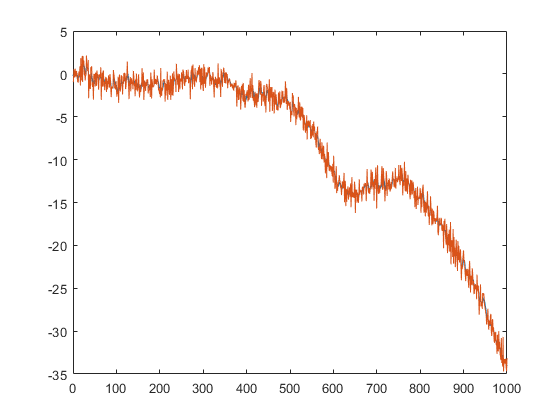

plot(samples, x_estimate(1,:), samples, y);

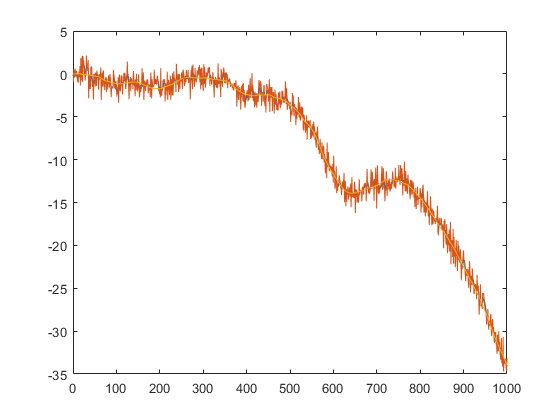

plot(samples, x_estimate(1,:), samples, y, samples, x_truth(1,1:1000));